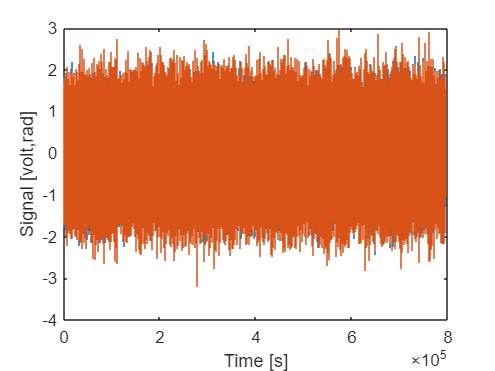

clear all; close all
%load("experiment_26_3.mat")
load("experiment_26_3_LOADSIDE.mat")

% Plot the measurement
figure(); clf();
stairs(d); hold on; stairs(u);
xlabel('Time [s]'); ylabel('Signal [volt,rad]');
hold off


%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010

%t_end = N_samples/fs

angle(exp(-100*stepsize*i))* 180/pi %phase los at 100 Hz due to discretization

ans = -1.4324


%removing uselss data 
N_trash = 1000; 
u = u(N_trash:end)

u =     0.3438
   -0.0935
    0.4863
   -0.8548
    0.9794
   -0.0934
   -0.4282
    0.2291
   -0.1497
    0.2101


d = d(N_trash:end)

d =     0.2999
   -0.1343
    0.4455
   -0.8925
    0.9417
   -0.1279
   -0.4596
    0.1976
   -0.1780
    0.1818


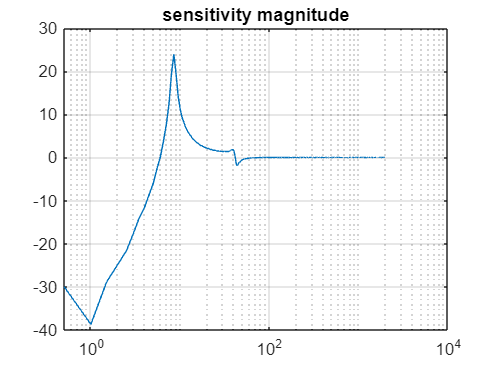


%window settings
min_freq = 0.5; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize/stepsize); %window size in data points 
n_overlap = round(nfft/5);

%Tf estimate
[Sud, F] = tfestimate(d,u,hann(nfft),n_overlap,nfft,fs); %cross spectral power density
Sdd = pwelch(d,hann(nfft)); %spectral power disturbance
Suu = pwelch(u,hann(nfft)); %spectral power input
%S =  Sud./Sdd; %sensitivity function
S = Sud;

figure()
semilogx(F,mag2db(abs(S)))
title("sensitivity magnitude")
grid on; hold off

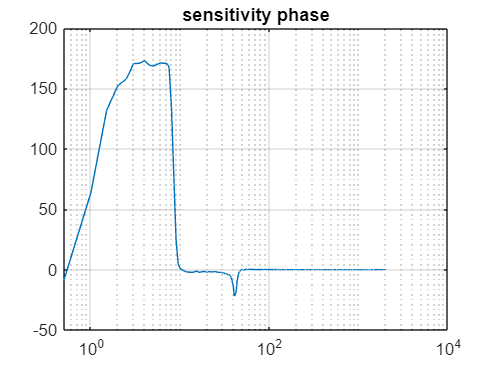


figure()
semilogx(F,angle(S)/pi*180)
title('sensitivity phase')
grid on; hold off

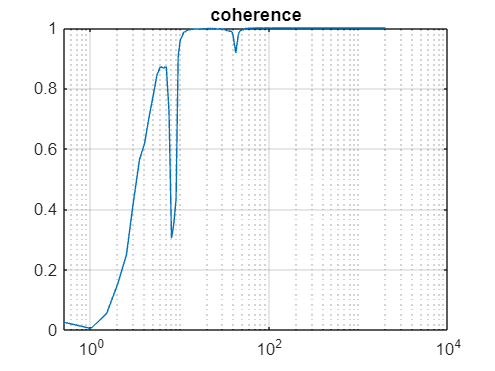


%plotting coherence 
figure()
[coherence_ry, f] = mscohere(d,u,hann(nfft),n_overlap,nfft,fs);
semilogx(f,coherence_ry)
title('coherence')
grid on; hold off

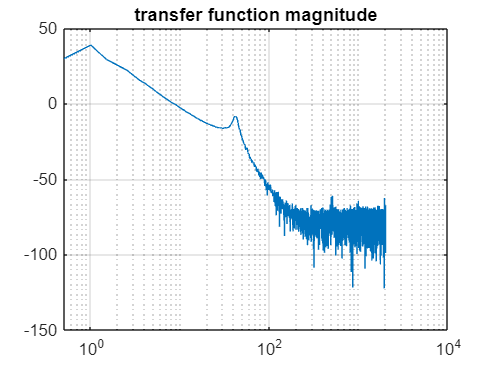

   
%plotting open loop transfer function
L = 1./S - 1;
figure()
semilogx(F,mag2db(abs(L)))
title('transfer function magnitude')
grid on; hold off

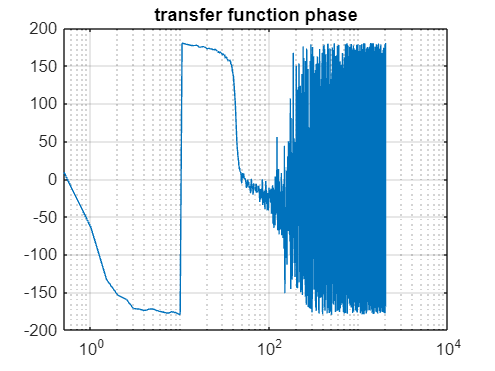


figure()
semilogx(F,angle(L)/pi*180)
title('transfer function phase')
grid on; hold off